x=[0.00001:0.00001:0.001]

x = 	1.0e+-3 *

    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900    0.5000


K=0.1;
R=2e-10;
D=1e-12;

t=[1:10:10000];
c0=95;

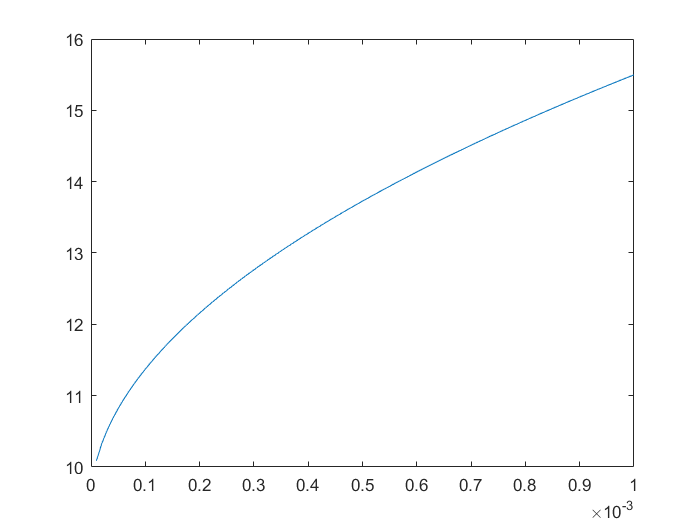

%% plotting the analytical solution of smith's function for concentration profile
%for i=1:length(t)
    e1=erf((((R/D)*x).^(1/2))/2);
    ex1=exp(-K*(1-K)*(((R/D)*x).^(1/2)));
    e2=(2*K-1)*ex1;
    e3=erfc(((2*K-1)*(((R/D)*x).^(1/2)))/2);
    cl=(c0/2)*(1+e1+e2.*e3);
    plot(x,cl)

    ax=gca;
    %set(gca, 'XDir','reverse')
    drawnow;    
    %title(sprintf("Time:%d",t(i)))
%end
